# フーリエ級数

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

ギターをかき鳴らすと、弦やギターボディの振動によって圧力波が発生します。録音されたギターの音の振幅が、ここでは時間領域でプロットされています。もしギターチューナーで使うために信号の基本周波数を知りたい場合、どうすればよいでしょうか？時間領域で信号をざっと見ても、あまり情報は得られません。信号を拡大してみると、繰り返しのパターンが現れます。しかし、この視点からでも、どの周波数が含まれているかを判断するのは困難です。この信号を解析するもっと簡単な方法があります。それは、周波数領域でプロットすることです。

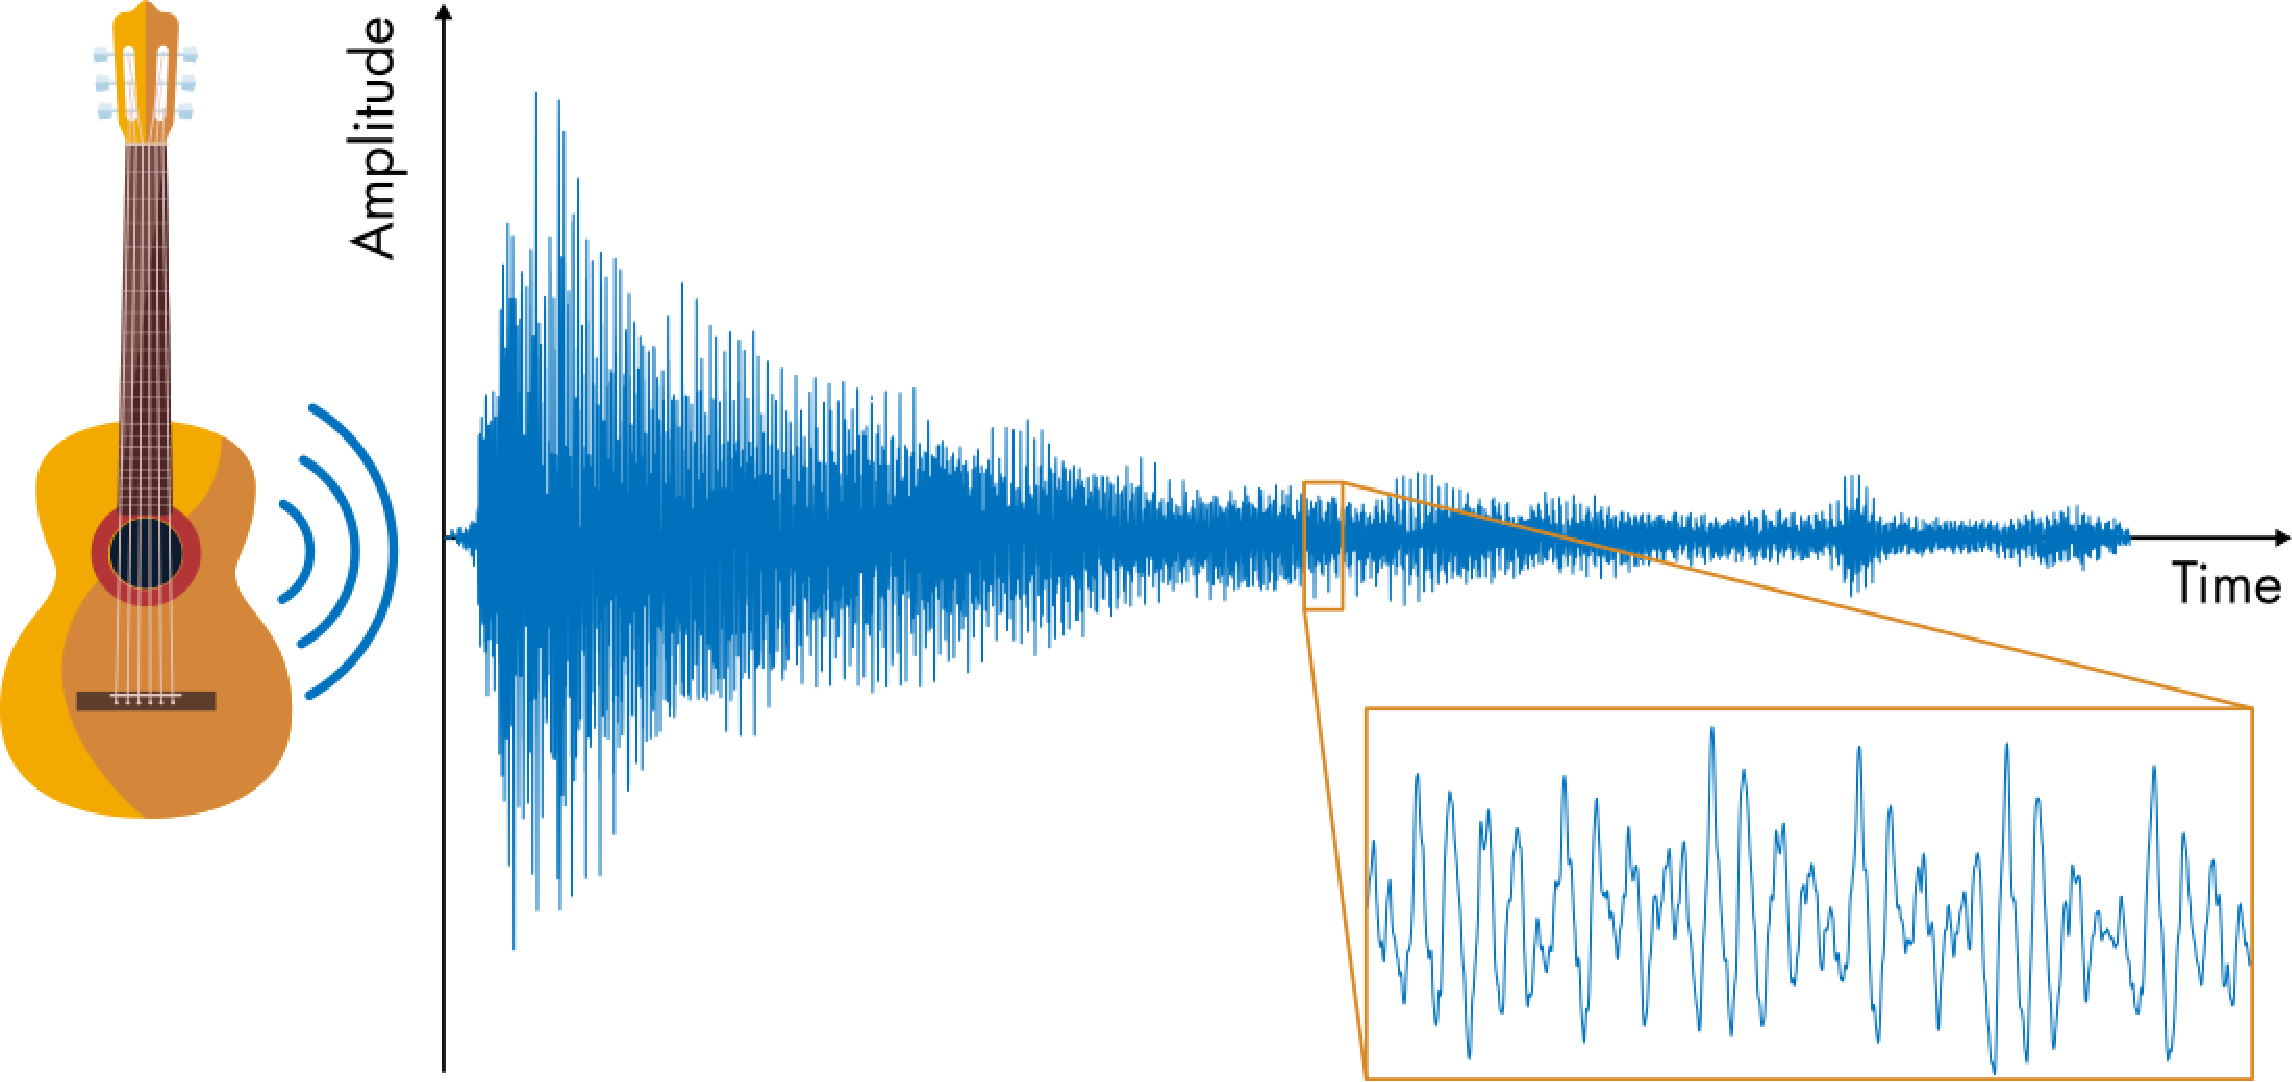

**始める前に：**

このライブスクリプトは、コードが表示され、出力がインラインで表示される状態で使用することを想定しています。MATLABツールストリップの**表示**タブの**表示**セクションで、**インラインで出力**を選択してください。または、ライブエディタウィンドウ右上のアイコン   を使って**インラインで出力**に設定することもできます。

 このライブスクリプトを操作することで、概念やコマンドの理解とともにMATLABに慣れることができます。さらに詳しい説明が必要な場合は、[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)（MATLABの基本を学べる無料の2時間オンラインチュートリアル）の受講を検討してください。

   最適な体験のために、指示や手順は示された順番で進めてください。前のセクションを完了してから新しいセクションに進みましょう。いくつかのセクションは前のセクションで作成された変数に依存しており、順番を守らないとエラーが発生します。

   と   のアイコンは、2種類のインタラクティブなアクティビティを示しています。   は、主にこのスクリプトで紹介された概念を、視覚的に理解するインタラクションを紹介します。 のインタラクションは、学習者が概念をどれだけ理解しているかを確認する目的で設計されており、教授による成績評価や完了チェックに使われる場合があります。

## 周波数領域

フーリエ解析とは、信号を時間領域（または空間領域）から*周波数領域*で解析することです。

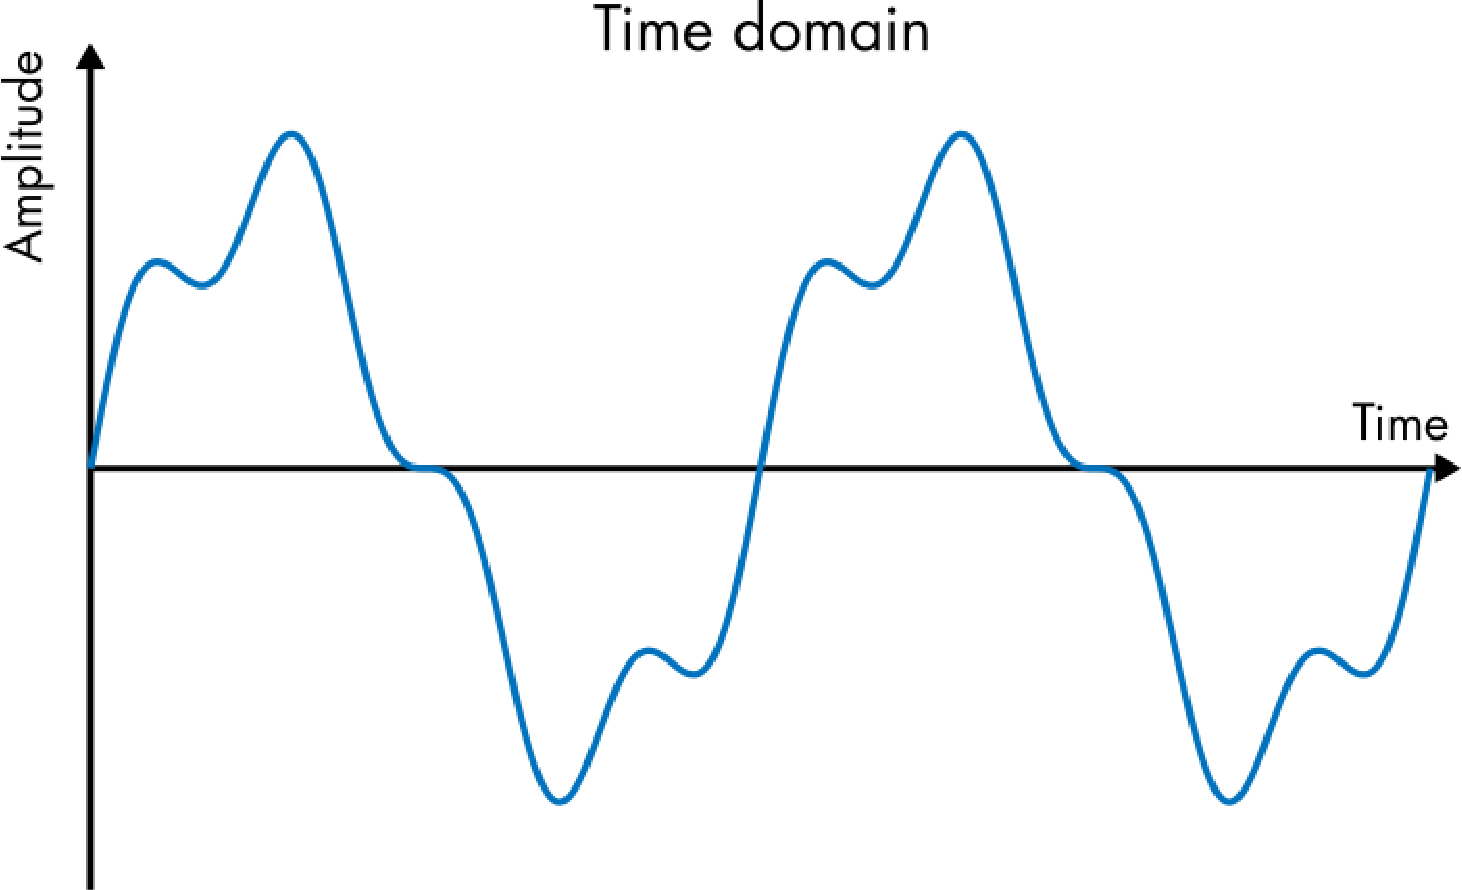 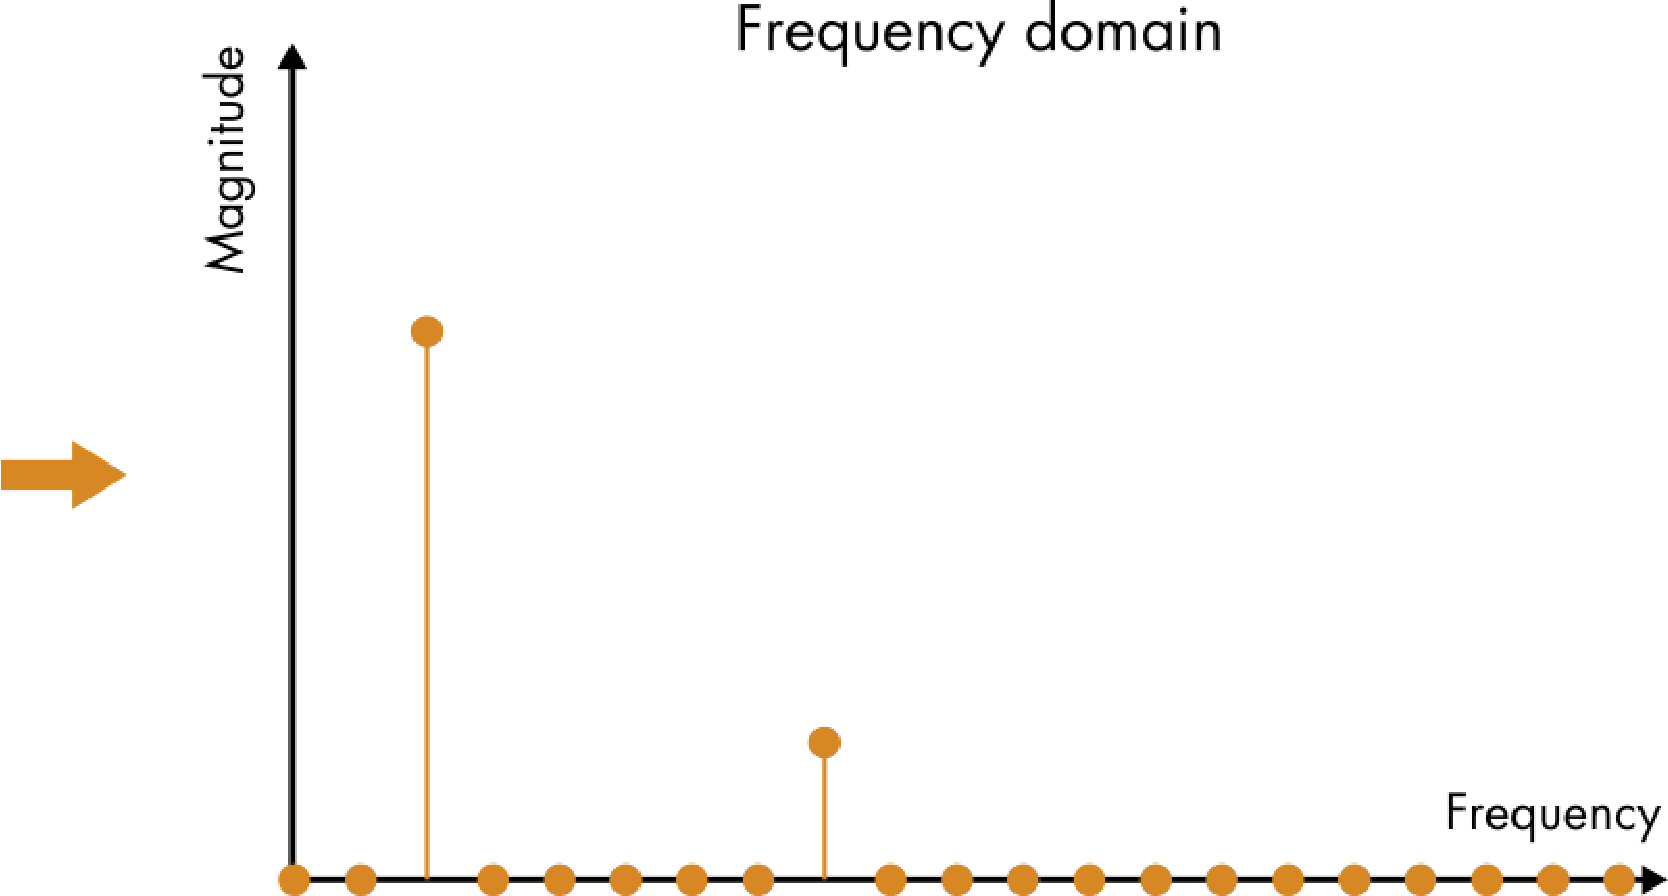

*時間領域と周波数領域における信号。時間領域では複雑に見える信号も、周波数領域で見ると実際には2つの正弦関数の単純な和です。*

信号に含まれる各周波数は、周波数領域でピークを作ります。その周波数が信号内で強いほど、周波数領域でのピークも大きくなります。

### 単一の正弦関数

次の関数を考えます


$$y(t) = A \sin( 2\pi f t)$$


この正弦関数の周波数は$f$ Hzです。ここで$f = 220$ Hzとします。時間領域で表すと、この関数は時間に対してプロットされ、通常の正弦波曲線が得られます。周波数領域では、この関数は220 Hzの位置に1つのピークとして表されます。振幅$A$は、周波数領域でのピークの高さを決めます。下のプロットは、時間領域と周波数領域の両方で$y$を示しています。

**課題.** このセクションを実行してプロットを生成してください。左側の青いバーをクリックします

  

または   **セクションを実行** を**ライブ エディター**タブの**セクション**からクリックします。

**課題.** スライダーを調整して曲線を変化させてみましょう。

- 正弦波の周波数$f$を増やすと、各プロットで何が起こりますか？

- 振幅$A$を大きくすると、プロットはどのように変化しますか？

f = 220;
A = 1.5;
plotSingleSine(A,f); % Helper function that generates the plots

   **アクティビティ.** 220 Hzの信号は特別で、「完全な」A音(ラ音)を表します。220 Hzの信号は、(1) 正弦波として生成し、(2) オーディオ信号として再生することで聴くことができます。

**タスク 1.** 時間変数`t`はすでに作成されています。`t`を使って、周波数220 Hz、振幅$A = 1$の正弦波信号`y`を作成してください。

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Compute your signal y here
Fc = 220;
y = 1*sin(2*pi*Fc*t)

**タスク 2.** [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) 関数を、次の構文で呼び出してオーディオ信号を再生してください。

ここで、`y`は信号、`Fs`はサンプリングレートです。その後、このセクションを実行して`y`をオーディオ信号として再生してください。

% Play the audio signal here


soundsc(y,Fs)

**タスク 3.** 周波数を2で割ったり掛けたりすると、同じ音名で1オクターブ高いまたは低い音になります。周波数を110 Hzに調整して、1オクターブ低いA音を聴いてみましょう。

### **実際の信号**

純粋な220 Hzの音はあまり魅力的に聞こえなかったかもしれません。楽器で奏でる音は、基本周波数に加えて複数の補助的な周波数（倍音と呼ばれる）を含み、より豊かな音を作り出します。以下のコマンドで再生されるギターの音を聴いてみましょう。

[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)

オーディオ信号をプロットすることで、時間領域でギターの音を解析できます。以下のMATLABコマンドは、録音されたギター音の信号のうち、およそ10ミリ秒分の波形を表示します。 

tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable
% Generate the plot
figure 
plot(tGuitar,yGuitar(:,1),"Linewidth",1)
xlim([0.1145 0.1245])
xlabel("t (s)")
ylabel("Amplitude")

 **考えてみましょう。** 

- この信号を、前のアクティビティでプロットした純粋な正弦波信号と比較してください。この信号を周波数領域で表現した場合、純粋なA音の正弦波信号で見られた単一のピークと比べて、どのように異なると予想されますか？

 **演習.** ギターのA音には、単一の基音周波数以上のものが含まれています。正確にいくつの倍音が存在するかを判断するのは難しいですが、3つの周波数を持つ関数を考えるのが良い出発点です。


$$y(t) = b_1 \sin( 2\pi f_1 t) + b_2 \sin( 2\pi f_2 t) + b_3 \sin( 2\pi f_3 t) $$


ここで、$b_i$は成分$i$の振幅、$f_i$はその周波数（Hz）です。下記の手順に従って、$y$を設計し、録音に近い音（できるだけ）を作ってみましょう。ギターのA音の基音は110 Hz、第一倍音は220 Hz、第二倍音は330 Hzです。これらの値を周波数$f_i$に使いましょう。最初は各$b_i = 1$と仮定します。事前定義された変数`t`を使って信号を作成してください。

**タスク 1.** MATLABで信号`y`を定義してください。

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Define the coefficients b1, b2, and b3
b1 = 0.5;
b2 = 2;
b3 = 0.3;
% Define the frequencies f1, f2, and f3 in Hz
f1 = 110;
f2 = 220;
f3 = 330;
% Create the signal y
y = b1*sin(2*pi*f1*t) + b2*sin(2*pi*f2*t) + b3*sin(2*pi*f3*t);

**タスク 2.** [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) 関数を使って、信号`y`を`t`に対してプロットしてください。[`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) 関数を使って$x$軸の範囲を`[0,0.01]`に調整しましょう。

plot(t,y)
xlim([0 0.01])
xlabel("t (s)")
ylabel("y")

**タスク 3.** [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) 関数を使って、作成した信号を再生してください。

soundsc(y,Fs)

**タスク 4.** 係数`bi`を調整して、プロットと音の両方でギター信号により近づけてみましょう。この信号では220 Hz成分が支配的です。生成される信号が完全に一致することはないので、3～4回程度調整してみてください。

 **考えてみましょう。** 

- ギター信号を再現するために$y(t)$に必要なものは何でしょうか？

## フーリエ正弦級数と余弦級数

実世界の周期的な信号を正確に再現するには、3つ以上の周波数が必要になることがよくあります。使用する周波数が増えるにつれて、多くの正弦項を含む関数の記述はますます複雑になります。代わりに、加算記法を使うことができます。例えば、前の例の関数を次のように書き直すことができます。


$$y(t) = \sum_{i=1}^3 b_i \sin( 2\pi f_i t) $$


フーリエ級数は、**周期的な**信号を無限個の周波数（理論上）で再現します。実際の信号処理では、有限個の周波数しか使いません。*フーリエ正弦級数*は、正弦関数の無限和です：


$$f(t) = \sum_{n=1}^\infty b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


$L$は関数$f$の周期性を決めるパラメータで、$f$の周期は$2L$です。つまり、$f$は常に$2L$ごとに周期的に繰り返されます。和の各項は*フーリエモード*と呼ばれます。例えば、基本モード（$n = 1$）は


$$f_1 = \sin \left( \frac{\pi}{L} t \right)$$
 

最初の係数$b_1$は、このモードが全体の和にどれだけ強く現れるかを決めます。

   **アクティビティ.** このアクティビティでは、Sine and Cosine Seriesアプリを使っていくつかの関数を作成します。リンクをクリックしてアプリを開き、下記のタスクを完了してください。

[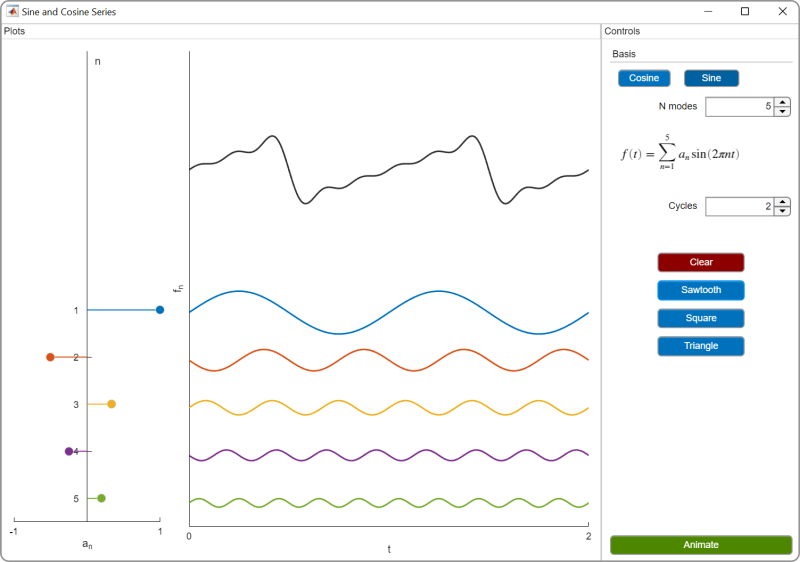](matlab: SinCosSeries)

[SinCosSeries.mlapp](matlab: SinCosSeries)

**タスク 1.** フーリエ基底を**Sine**に設定してください。

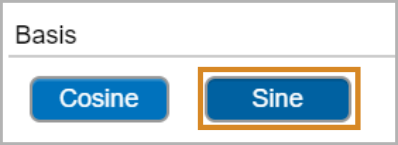

**タスク 2.** 表示されている信号を作成してください。そのためには、フーリエ係数をクリック＆ドラッグして$a_1 = 1$、$a_3 = -1$に設定します。これらは左側のstemプロットにあります。

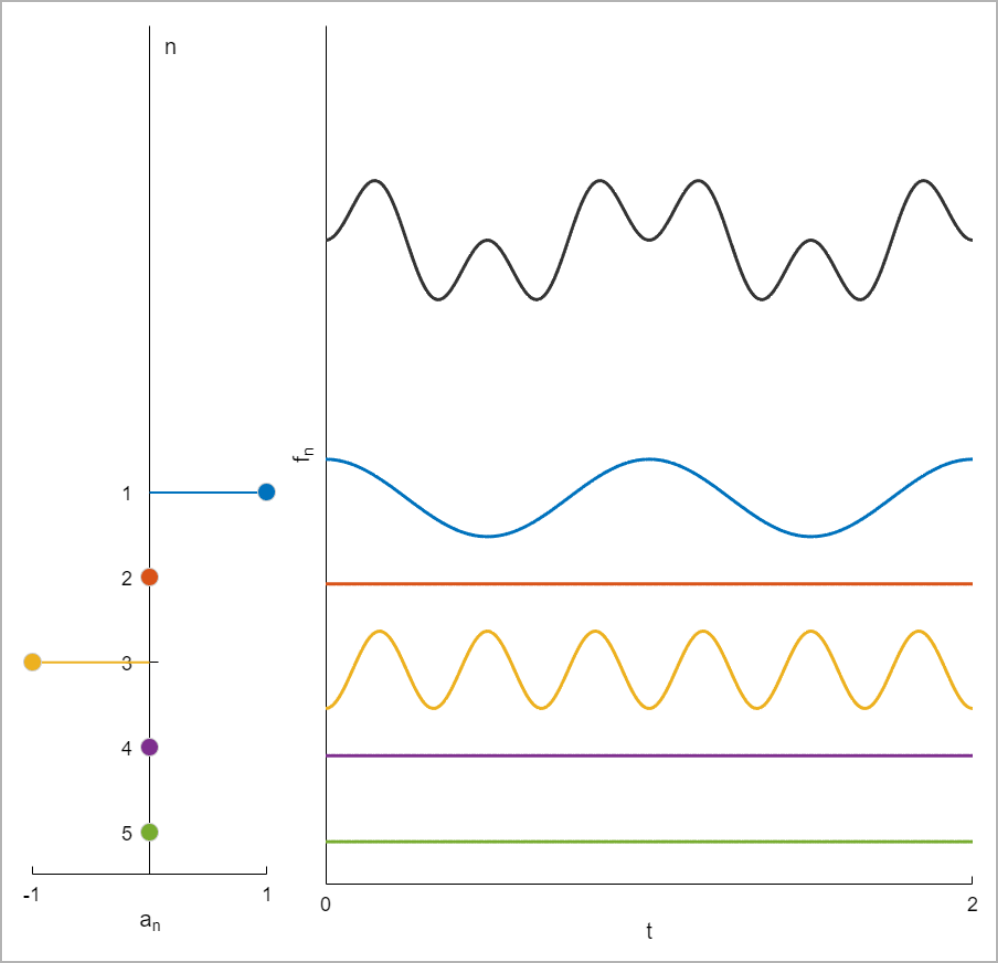

**タスク 3.** **Animate**ボタンをクリックして、各成分がどのように合成されて全体の関数になるかを確認しましょう。

**タスク 4.** フーリエ係数を（おおよそ）$a_1 = 1$, $a_2 = 0.5$, $a_3 = 0.25$, $a_4 = 0.125$, $a_5 = 0.0625$に調整し、プロットをアニメーションさせてください。どのような波形が生成されますか？

**タスク 5.** フーリエ係数を調整して、下図の波形を再現してください（**正弦基底(Sine)**を使いましょう）。

(a) 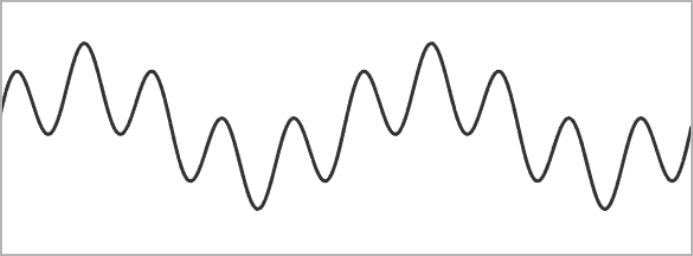

(b) 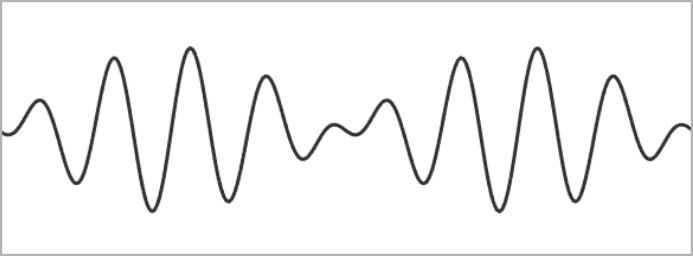

**ヒント**: 信号(b)を再現するには、隣り合う2つの周波数を使いましょう。

## フーリエ級数

フーリエ正弦級数には無限に多くの周波数が含まれています。これにより、級数はさまざまな波形を生成できます。しかし、正弦モードだけを使って生成されるすべての周波数は*位相*がゼロになります。

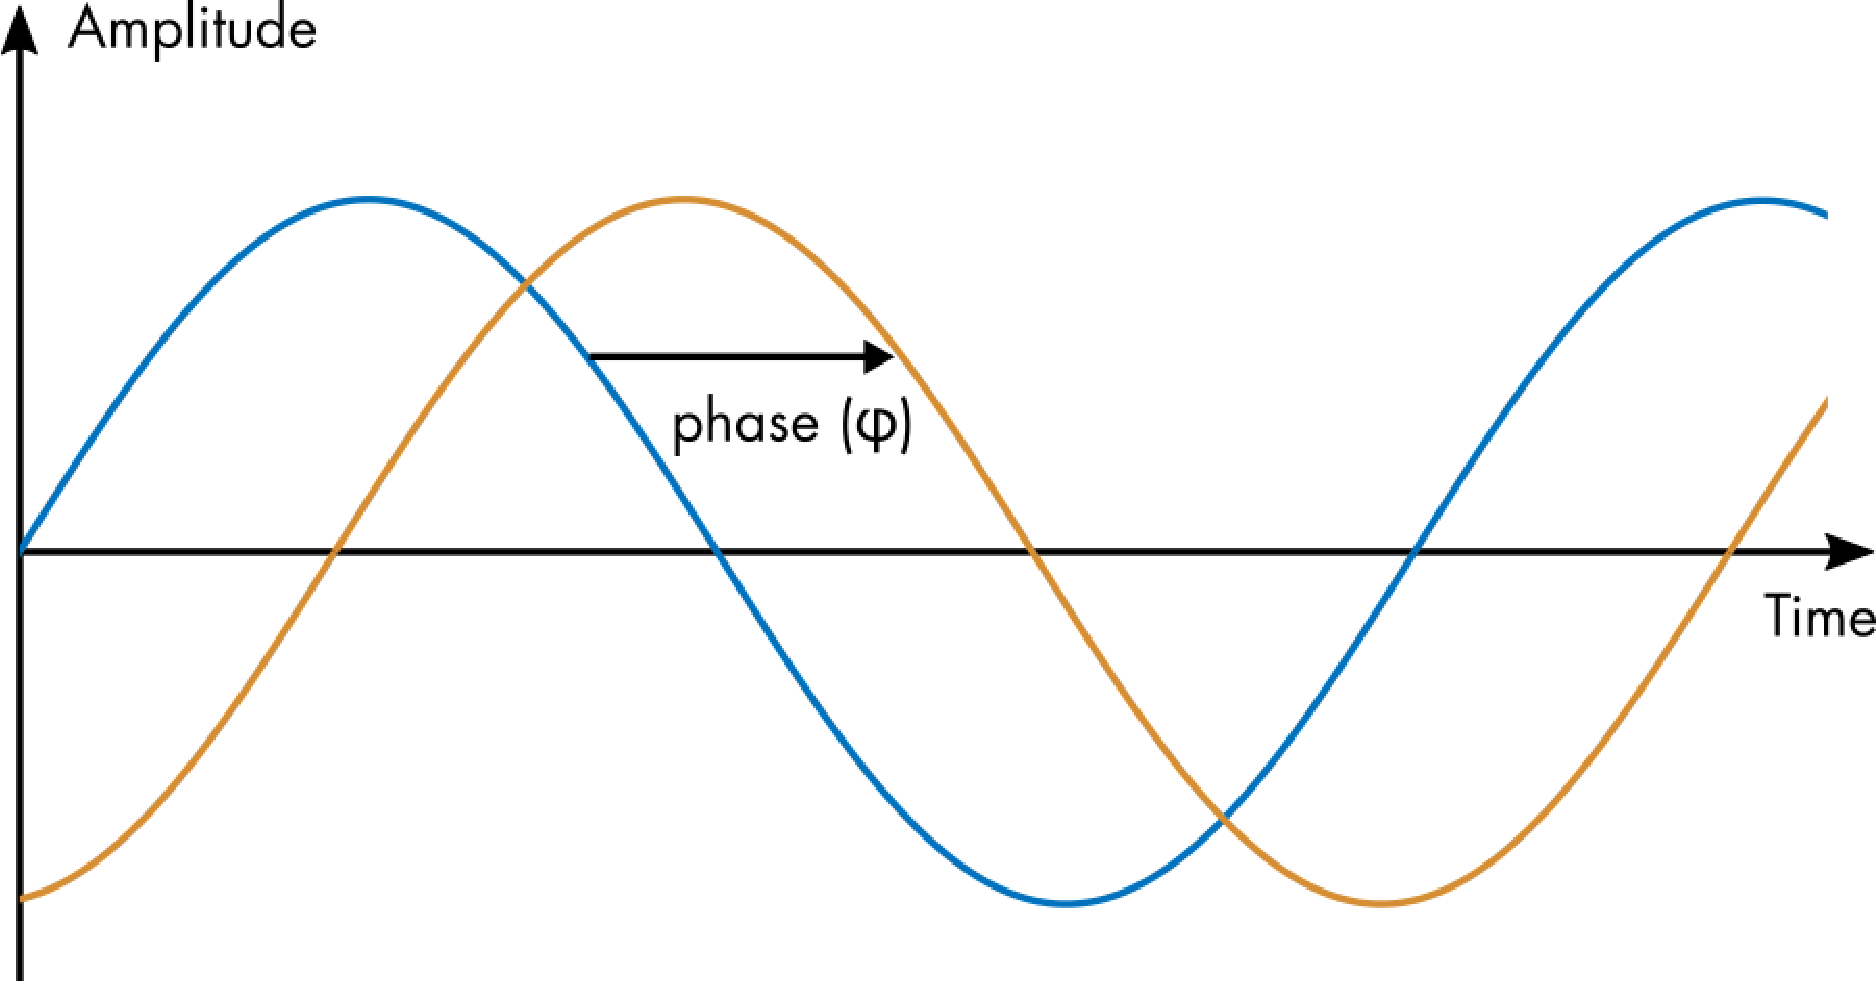

*信号の位相または位相シフトとは、水平方向にどれだけずれているかを表します。*

実信号は通常、位相がゼロではないため、フーリエ正弦級数だけでは表現できません。しかし、余弦級数を加えることで、任意の位相を持つ信号を生成できます。

### **定義**

フーリエ級数の標準的な定義の一つは、余弦級数と正弦級数の和です：


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


この追加により、係数は2組存在することになります。余弦級数の係数$a_n$と正弦級数の係数$b_n$の2組の係数が現れます。正弦項は$0^\circ$の位相を持ち、余弦信号は$90^\circ$の位相を持ちます（ゼロ位相が正弦信号に対応すると仮定）。同じ周波数の余弦信号と正弦信号を組み合わせると、位相シフトした信号が生成されます：


$$a \cos (\omega t) + b \sin( \omega t) = c \sin( \omega t  -  \phi)$$


ここで、係数$a$と$b$の比が位相シフト$\phi$を決定します。

   **アクティビティ.** 下記のタスクを完了して、フーリエ級数を使って位相シフトした信号を作成しましょう。

**タスク 1.** インタラクティブ・フーリエ級数アプリを開いてください。

[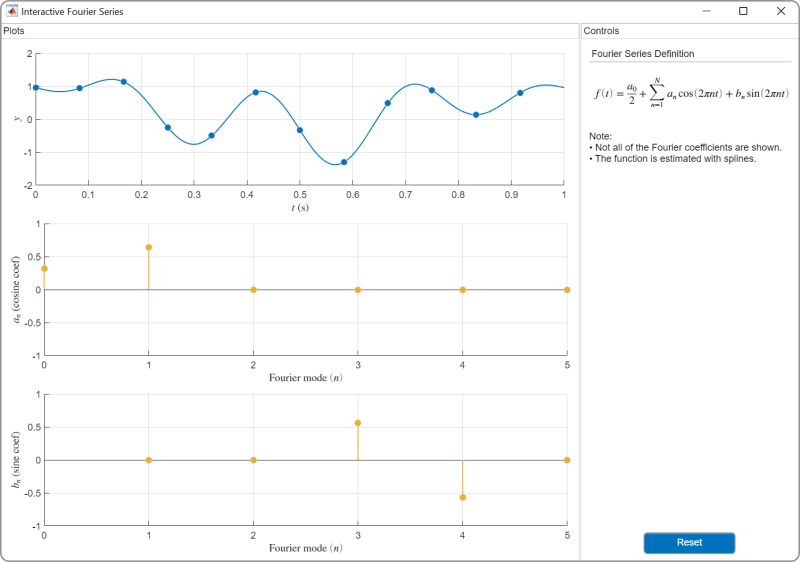](matlab: InteractiveFourierSeries)

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

アプリでは、$L = 1/2$がで設定されているので、フーリエ級数の周期は1秒です。つまり、インデックス$n = 1$の基本モードの周波数は1 Hzです。モード係数を調整するには、黄色い円をクリック＆ドラッグしてください。この演習では青い円は動かさないでください。

**タスク 2.** フーリエ係数を調整して、1 Hzで位相ゼロ（$\phi = 0 ^\circ$、正弦関数に対して）の信号を作成してください。

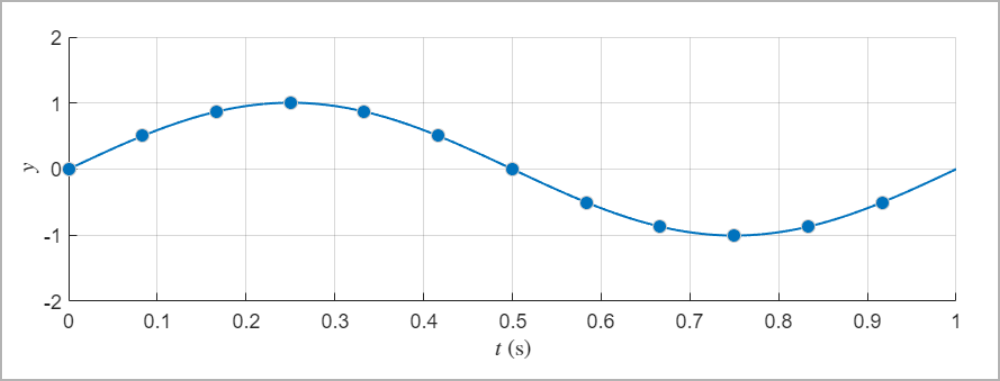

**タスク 3.** フーリエ係数を調整して、2 Hzで位相シフト$\phi = 90 ^\circ$（正弦関数に対して）の信号を作成してください。

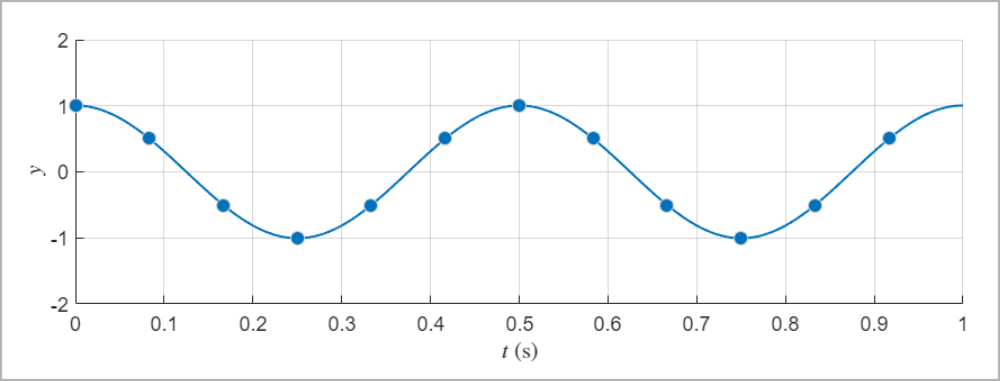

**タスク 4.** 1 Hzで位相シフト$\phi = 45^\circ$（正弦関数に対して）の信号を作成してください。

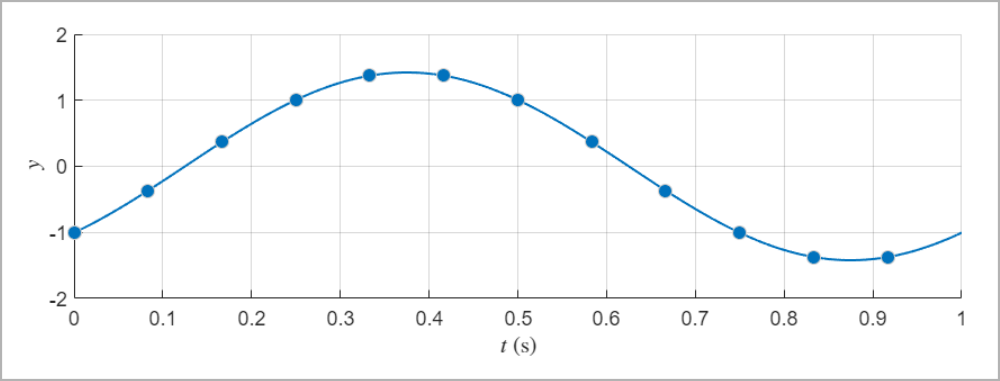

## フーリエ級数の係数の求め方

ギターのA音のオーディオ信号には、明らかに少なくとも3つの周波数が含まれています。

**タスク.** このセクションを実行してギター音の信号を表示してください。

% This code plays the guitar sound and plots part of the signal
[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)
plotGuitarSignal(yGuitar,FsGuitar,[0.3 0.33])
 

しかし、どのような周波数が含まれていて、それぞれがどれだけ強く表現されているのでしょうか？言い換えれば、ギターのオーディオ信号は周波数領域でどのように見えるのでしょうか？

### フーリエ係数の公式

前のアクティビティでは、フーリエ係数を手動で調整しました。幸いなことに、与えられた信号のフーリエ級数の係数を特定するために手動で調整する必要はありません。2つの公式を使って係数を求めることができます：


$$a_n = \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} y(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


これらの積分は、元の信号$y(t)$に一致させるために必要な各周波数成分(モード)の重みを計算します。各モードは固有の周波数を持つため、積分によって元の信号$y(t)$に各周波数がどれだけ強く含まれているかが決まります。ただし、関数$y(t)$をフーリエ級数で表すには、周期$2L$で周期的である必要があります。周期的でない場合、導出されたフーリエ級数は$y(t)$と完全には一致せず、その信号を周期$2L$で繰り返したものとして近似されます。

下のグラフは、積分式と台形則を使用して推定されたギター信号のフーリエモード(周波数成分)を示しています。

**タスク.** このセクションを実行して、周波数領域でギターのA音を見てみましょう。

% Helper functions that estimate and plot the Fourier coefficients
[freq,a,b] = computeGuitarFourierCoef(yGuitar,FsGuitar);
plotGuitarCoef(freq,a,b)
 

グラフ上のピークをクリックするとデータチップが表示され、各モードの周波数を確認できます。

 **考察しましょう。**

- どの周波数が支配的ですか？

- 支配的な周波数は純粋なサイン波またはコサイン波ですか？

- 観察された係数から、各周波数成分(モード)の位相について何か言えることはありますか？

## **フーリエ級数の大きさと位相**

### **大きさ**

上の周波数領域のグラフを見ると、330 Hzの信号が220 Hzの信号とほぼ同じ振幅を持っているように見えるかもしれません。しかし、実際にはそうではありません。なぜなら、周波数の大きさは両方の係数の組み合わせだからです。具体的には、$n$番目のモードの大きさは


$$A_n = \sqrt{ {a_n}^2 + {b_n}^2 }$$


 **演習。**

**タスク1.** 前のセクションを実行して、変数 `freq`、`a`、`b` を作成してください。

**タスク2.** ベクトル `a` と `b` から係数の大きさ（$A_n$）を計算してください。結果は `A` に保存します。

  **プロ・ヒント。** ベクトルに対して要素ごとの演算を行うには、ピリオドを前置します。たとえば、係数ベクトル `a` の2乗を計算するには `a.^2` を使います。

% Compute A here
% A should be a vector that contains the magnitudes
A = sqrt(a.^2 + b.^2);

**タスク3.** `A` の大きさを `freq` の周波数に対して [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) プロットで描画してください。周波数の範囲は [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) 関数を使って [0,600] に設定します。

stem(freq,A)
xlim([0 600])
ylabel("Magnitude")
xlabel("Frequency [Hz]")

 **考察しましょう。**

- どの周波数が支配的ですか？

- ギターA音の基本周波数は110 Hzです。このグラフはギターA音として妥当ですか？

### **大きさと位相のプロット**

周波数領域は、係数 $a_n$ と $b_n$ をプロットするか、または大きさ $A_n$ をプロットすることで可視化できます。しかし、大きさだけでは全てを把握することはできません。より完全な理解のためには、位相のプロットを加えるとよいでしょう。

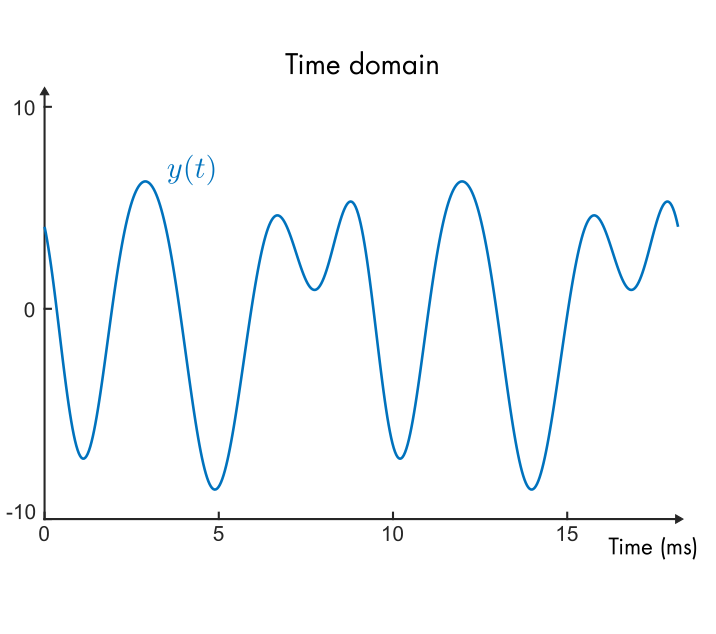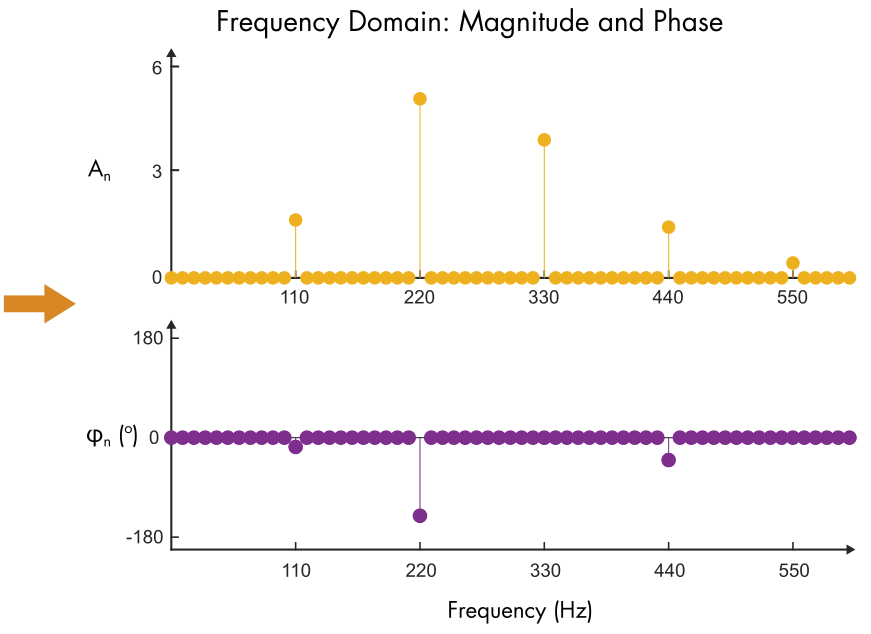

*ギターA音の主な5つのモードの* *時間領域と周波数領域での信号。*

*ここでは、周波数領域を大きさと位相でプロットしています。*

このプロットは、$a_n$ と $b_n$ のプロットよりも情報の把握に適しています。なぜなら、各モードの2つの直感的な特徴を明確に示しているからです：

- **大きさ**：モードの強さ

- **位相**：モードが時間軸上でどれだけシフトしているか

### 定義

フーリエ級数の各モードを大きさと位相で表す形で、次のように定義されます：


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


ここで、

$A_n = \sqrt{a_n^2 + b_n^2}$     および    $\phi_n = \text{atan2}\left( b_n,a_n\right)$

位相角は2引数のarctanで計算されます。MATLABでは、これは [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) 関数で実装されています。

   **アクティビティ。** このアクティビティでは、2つの周波数領域表現（サイン-コサイン表現と大きさ-位相表現）を比較します。

**タスク1.** フーリエ級数：大きさと位相アプリを実行してください。

[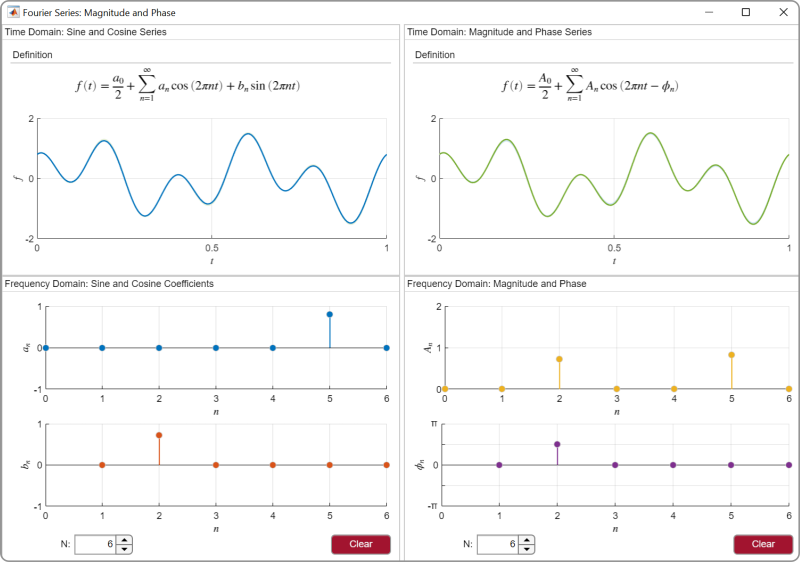](matlab: run MagnitudePhase.mlapp)

[`MagnitudePhase.mlapp`](matlab: run MagnitudePhase.mlapp)

左側のパネルには周波数領域のsin-cosバージョン（$a_n$ と $b_n$）が表示されます。右側のパネルでは、大きさ（$A_n$）と位相（$\phi_n$）が使われています。

**タスク2.** $a_1 = -1$ に設定し、他の $a_n, \ b_n = 0$ のままにしてください。係数を調整するには、stemプロットをクリック＆ドラッグできます。最初の時系列プロットは下図のように表示されるはずです。

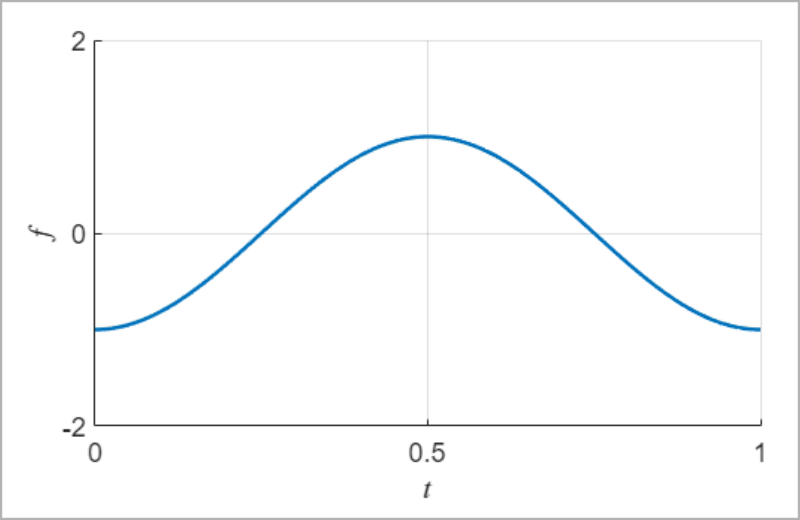

**タスク3.** 2つ目のパネルで大きさ（$A_n$）と位相（$\phi_n$）を調整して、**タスク2**のプロットを再現してください。

**タスク4.** 両方のプロットをクリアし、1つ目のパネルで周波数領域係数 $a_n$ と $b_n$ を調整して、次の関数を作成してください：


$$f(t) = 0.5 - \sin(4 \pi t) + \cos( 4 \pi t)$$


正しくできていれば、下図のような時系列が表示されます。

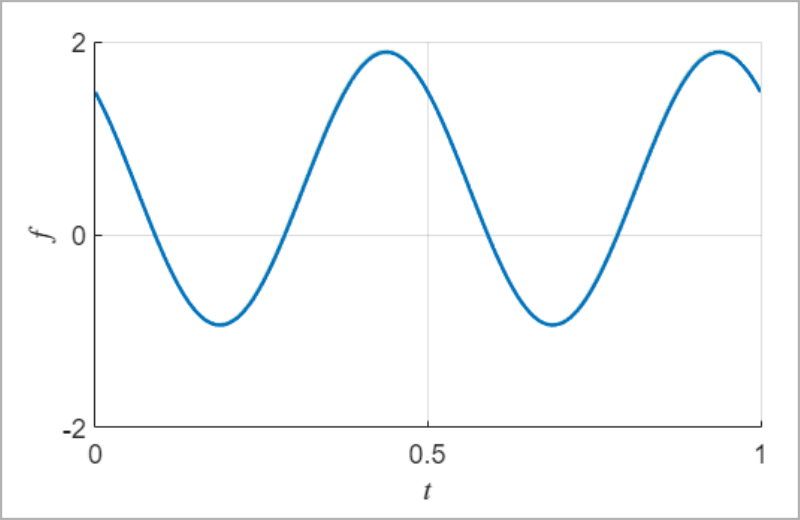

**タスク5.** 2つ目のペイン（右側）で大きさ $A_n$ と位相 $\phi_n$ のパラメータを調整して、**タスク4**の時系列関数 $f(t)$ を再現してください。正しければ、2つ目の時系列プロットは**タスク4**のものと一致するはずです。

**ヒント**：$n = 0$ と $n = 2$ のモードパラメータだけを調整すれば十分です。

**タスク6.** 次の関数についても**タスク4**と**タスク5**を繰り返してください


$$f(t) = \sin(2 \pi t) + \cos( 2 \pi t) + 0.5 \sin (12 \pi t)$$


[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

**補助関数**

function plotSingleSine(A,f)
    % Creates the plot of a sine function in 
    % the time and frequency domains

    % Time domain
    t = linspace(0,0.01,500);
    g = A*sin(2*pi*f*t);
    
    % Frequency domain
    freq = 0:500;
    ghat = zeros(1,501);
    ghat(f+1) = A;
    
    figure("Position",[1 1 800 325])
    % Time domain plot
    subplot(1,2,1)
    plot(t,g,"linewidth",1)
    ylim([-3,3])
    title("Time domain")
    xlabel("time (s)")
    ylabel("Amplitude")
    
    % Frequency domain plot
    subplot(1,2,2)
    stem(freq,ghat,"filled")
    ylim([0,3])
    title("Frequency domain")
    xlabel("frequency (Hz)")
    ylabel("Magnitude")
end

function plotGuitarSignal(yGuitar,FsGuitar,timeLimits)
    % Creates and labels the amplitude plot
    % for the guitar signal

    tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable    
    % Generate the plot
    figure("Position",[1 1 900 325]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlim(timeLimits)
    xlabel("t (s)")
    ylabel("Amplitude")
    title("Time domain")
end

function [freq,a,b] = computeGuitarFourierCoef(y,Fs)
    % Estimates the coefficients for the Fourier
    % series using the trapezoid rule

    Nmodes = 1000;
    yc = y(1e4:2e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    freq = (1:Nmodes)/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    a = zeros(1,Nmodes);
    b = zeros(1,Nmodes);
    a0 = 1/L*trapz(tc,yc);
    for n = 1:Nmodes
        a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
        b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
    end
end

function plotGuitarCoef(f,a,b)
    % Plots the guitar coefficients
    % and adds labels

    % Plot the result
    figure("Position",[1,1,900,325])
    stem(f,a,"Filled")
    hold on
    stem(f,b,"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient")
    legend("a_n","b_n")
    title("Frequency domain")
    xlim([0,600])
end

